# Программа подсчета коэффициентов по ареотерме

За стандартную полагается ареотерма из Bertka, Fei, 1997:

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:B20";

% Specify column names and types
opts.VariableNames = ["Pressure_Bar", "Temperature_K"];
opts.VariableTypes = ["double", "double"];

% Import the data
Ar = readtable("/Users/astrobirf/Desktop/Perple_X/Areoterm/areoterm.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Display results
Ar

Ar = 19×2 table
    Pressure_Bar    Temperature_K
    ____________    _____________

         20000          1373     
         30000          1473     
         40000          1523     
         50000          1523     
         60000          1673     
         70000          1723     
         80000          1773     
         90000          1823     
         1e+05          1848     
       1.1e+05          1923     
       1.3e+05          1973     
      1.35e+05          1983     
       1.4e+05          1998     
       1.5e+05          2023     
       1.7e+05          2023     
       1.9e+05          2023     


 Далее посчитаем 


x = table2array(Ar(:,"Pressure_Bar"));
y = table2array(Ar(:,"Temperature_K"));
p = polyfit(x, y, 4);

Ниже укажем коэффициенты полинома, начиная со старшей степени:


$$T = pr_1 P^4 + pr_2 P^3 + pr_3 P^2 + pr_4 P + pr_5$$


pr = [1.008919e-18 -4.803016e-13 5.130797e-8 4.619979e-3 1.274985e3];
yfit = polyval(p,x);
yrfit = polyval(pr,x);
err = max(abs((yrfit - yfit)./(yfit - y))*100)

err = 0.7877

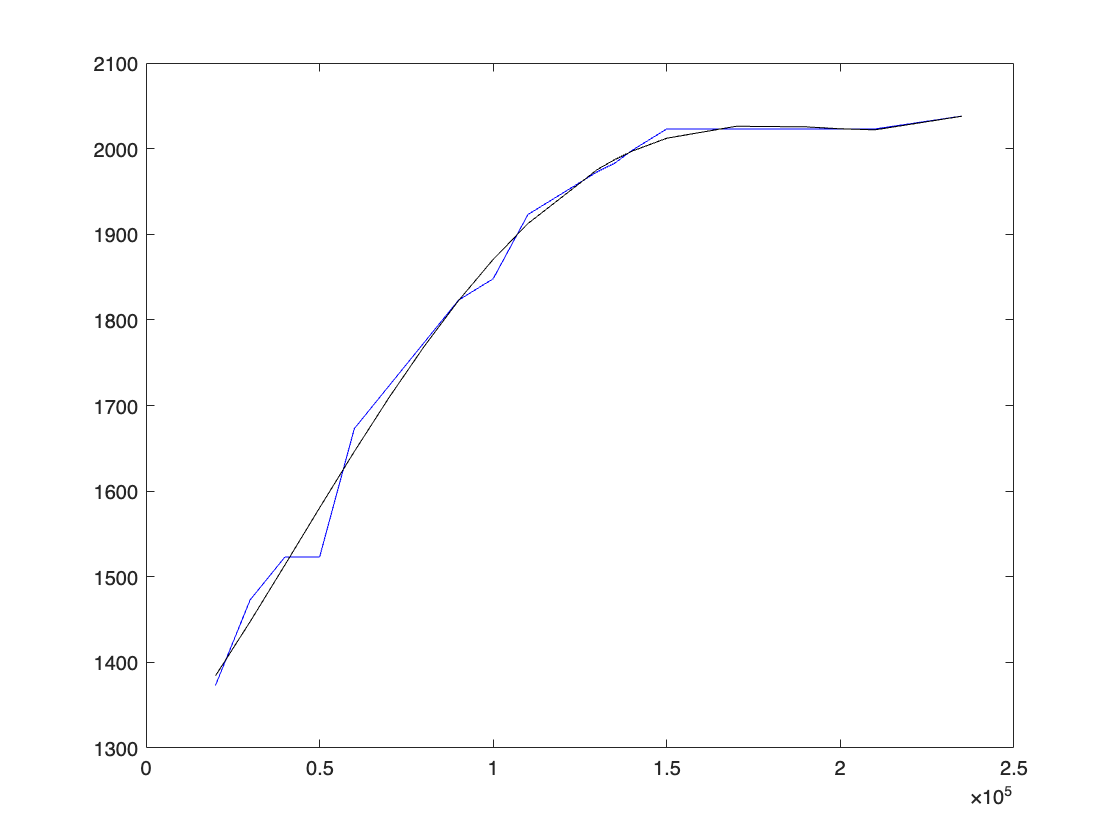

figure()
plot(x, y, 'b', x, yrfit, 'k')